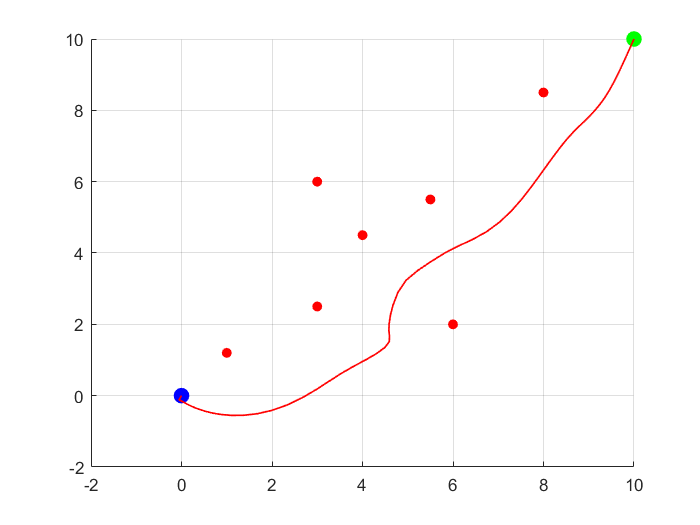

close all;clear;clc;

%参数给定
obstacle = [1 1.2;3 2.5;4 4.5;3 6;6 2;5.5 5.5;8 8.5]; %障碍位置
qgoal = [10,10]; %目标点
x0 = [0 0];     %起始点
stepSize = 0.1;  %步长
iter = 1000;     %迭代次数
epsilon = 0.8;   %引力尺度因子
eta = 0.2;       %斥力尺度因子
dgoal = 5;     %引力分段函数分界值
r0 = 3;       %超过这个距离就没有斥力了
path = x0;  %记录轨迹的矩阵
threshold = 0.5;
%开始循环
q = x0;         %初始化位置
for i = 1 : iter
    Attraction = attraction(q,qgoal,dgoal,epsilon);   %引力
    Repulsion = repulsion(q,obstacle,r0,eta,qgoal);   %斥力
    compositeForce = Attraction + Repulsion;  %引力与斥力的合力(如果陷入局部最优可以加normrnd(0, 0.7, 1,2))
    q = q + stepSize * compositeForce;   %更新位置
    path = [path;q];
    if distanceCost(q,qgoal) < threshold
        path = [path;qgoal];
        break;
    end
end
figure(1)
scatter(obstacle(:,1),obstacle(:,2),'filled','r'); %绘制障碍点
hold on;
scatter(qgoal(1),qgoal(2),88,'filled','g')   %绘制目标点
scatter(x0(1),x0(2),88,'filled','b')          %绘制起始点
plot(path(:,1),path(:,2),'LineWidth',1,'Color','r');    %绘制路径
grid on;